# 2. Finding Natural Patterns in Data

## Dimensionality Reduction

When the dimension is large, it is difficult to visualize the data to look for patterns or groups. You can try to visualize the data by transforming it into a 2 or 3 dimenstional coordinate space.

load('bbstats.mat')

### 1. Multidimensional scaling

% open("2_1 Multidimensional Scaling.pdf") % Read this file before start
d=pdist(statsnorm);
[x,e]=cmdscale(d)

x =    -2.5485    1.2178   -0.0925   -0.7242   -0.4860   -0.0325    0.0950   -0.2356   -0.2837   -0.0311    0.2154   -0.3464    0.2172    0.0978   -0.0238   -0.0171   -0.0054
    2.1322   -3.1352    0.3102   -0.3670    0.3826    0.3179   -1.2126   -0.9061   -1.0428    0.1654    0.3707   -0.0027    0.2806   -0.0609   -0.0598    0.0183   -0.0009
   -0.5333    0.3654    0.7177   -0.3299   -0.3373    0.2117   -0.1612    0.2554   -0.3007    0.3865   -0.0195   -0.2278   -0.2815   -0.1042   -0.0117    0.0792    0.0072
    5.6463    2.3930    0.8472   -1.4487   -0.0339    0.2938   -0.2370    0.1329    0.2902   -0.3182   -0.1195   -0.1888   -0.2257    0.0342   -0.1956    0.0093    0.0063
   -2.6830    1.7338    0.0975    0.5254   -0.6947    0.3721   -0.4348    0.1247    0.3378   -0.8879    0.1100    0.3024    0.1182    0.0186   -0.0138   -0.0294   -0.0056
    5.5690   -4.4839    0.8503    0.2245    0.0946   -0.3723    0.5065    0.2828    0.8058    0.0967    0.2446    0.3213    0.3334   -0.4159 

e = 	1.0e+03 *

    9.4009
    5.1765
    1.2410
    0.7806
    0.4912
    0.4028
    0.3401
    0.2905
    0.2732
    0.1683


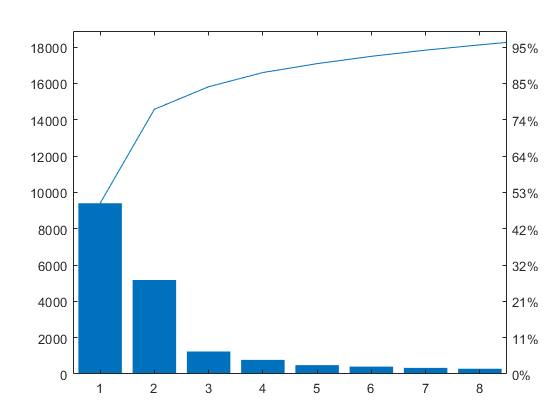

pareto(e)

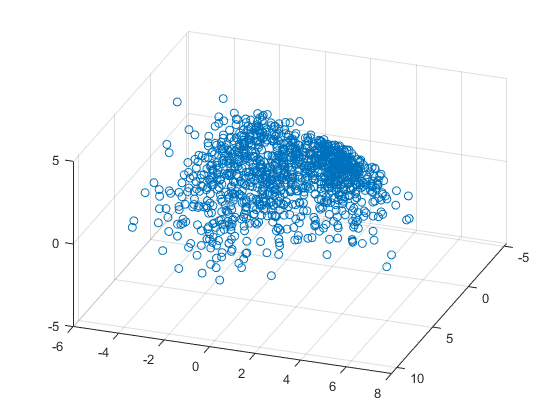

figure
scatter3(x(:,1),x(:,2),x(:,3))
view(110,40)

### 2. Principal Component Analysis

% open("2_2 Principal Component Analysis.pdf") % Read this file before start
[pcs,scrs,~,~,pexp]=pca(statsnorm)

pcs =    -0.0437    0.3955    0.3115    0.0918   -0.0149   -0.1874   -0.2443    0.1325    0.3497    0.6914    0.1448   -0.0396    0.0033   -0.0037    0.0285   -0.0017   -0.0008
   -0.0400    0.3831    0.2786    0.1518   -0.4145   -0.2100   -0.4238   -0.0256    0.0359   -0.5788   -0.0979   -0.0668    0.0620    0.0170   -0.0211    0.0028    0.0005
    0.3266    0.0065    0.0355   -0.1691   -0.0018    0.0860    0.0323   -0.2343    0.1017    0.0899   -0.3122   -0.3878    0.7256   -0.0758    0.0255    0.0283    0.0110
    0.3339   -0.0080    0.0895    0.1877    0.0352    0.0885    0.1012   -0.0254    0.1896   -0.0920    0.0995   -0.0602   -0.1914   -0.3528   -0.0501    0.1608    0.7602
    0.1234    0.3747   -0.0763   -0.2075   -0.0429    0.5652   -0.1010    0.0311   -0.2442   -0.0415    0.6038   -0.1289    0.0862    0.0912   -0.0671    0.0017   -0.0135
    0.2211    0.2986    0.0536   -0.1822    0.0992    0.2671   -0.2173   -0.3435   -0.2658    0.1699   -0.5307    0.2805   -0.3444   -0.025

scrs =    -2.5485    1.2178    0.0925    0.7242   -0.4860   -0.0325   -0.0950   -0.2356    0.2837    0.0311    0.2154    0.3464   -0.2172   -0.0978   -0.0238    0.0171   -0.0054
    2.1322   -3.1352   -0.3102    0.3670    0.3826    0.3179    1.2126   -0.9061    1.0428   -0.1654    0.3707    0.0027   -0.2806    0.0609   -0.0598   -0.0183   -0.0009
   -0.5333    0.3654   -0.7177    0.3299   -0.3373    0.2117    0.1612    0.2554    0.3007   -0.3865   -0.0195    0.2278    0.2815    0.1042   -0.0117   -0.0792    0.0072
    5.6463    2.3930   -0.8472    1.4487   -0.0339    0.2938    0.2370    0.1329   -0.2902    0.3182   -0.1195    0.1888    0.2257   -0.0342   -0.1956   -0.0093    0.0063
   -2.6830    1.7338   -0.0975   -0.5254   -0.6947    0.3721    0.4348    0.1247   -0.3378    0.8879    0.1100   -0.3024   -0.1182   -0.0186   -0.0138    0.0294   -0.0056
    5.5690   -4.4839   -0.8503   -0.2245    0.0946   -0.3723   -0.5065    0.2828   -0.8058   -0.0967    0.2446   -0.3213   -0.3334    0.41

pexp =    49.7745
   27.4075
    6.5706
    4.1332
    2.6006
    2.1326
    1.8005
    1.5383
    1.4464
    0.8912


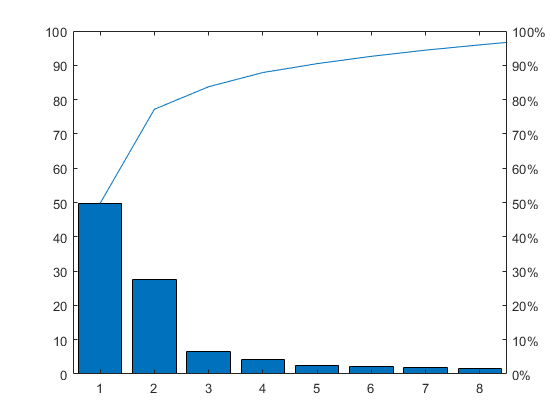

pareto(pexp)

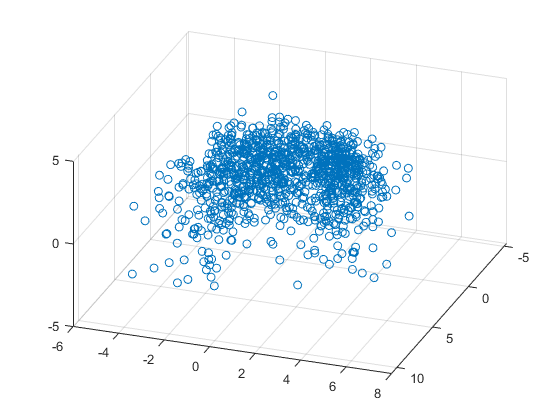

figure
scatter3(scrs(:,1),scrs(:,2),scrs(:,3))
view(110,40)

## Unsupervised Learning

### 1. k-Means Clustering(1/3)

% open("2_3 k-Means Clustering.pdf") % Read this file before start
g=kmeans(statsnorm,2);
[g,c]=kmeans(statsnorm,2,"Replicates",5)

g =      2
     1
     2
     1
     2
     1
     2
     2
     1
     2


c =    -0.1189   -0.1348    1.1668    1.1790    0.4238    0.7821    0.8218    0.8805    0.2913    1.1182    0.6549    1.1621    1.1629    1.0606    1.0849    0.5840    0.5631
    0.0542    0.0614   -0.5315   -0.5370   -0.1930   -0.3562   -0.3743   -0.4010   -0.1327   -0.5093   -0.2983   -0.5293   -0.5297   -0.4831   -0.4942   -0.2660   -0.2565


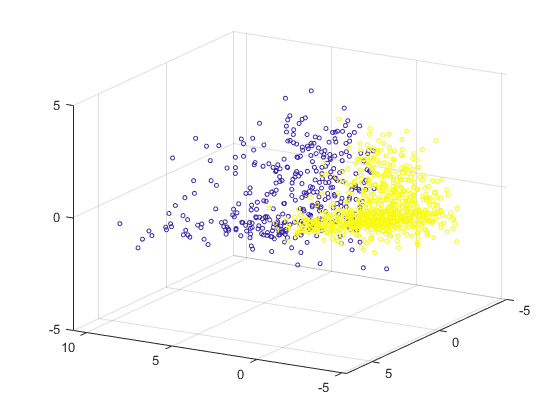

scatter3(scrs(:,1),scrs(:,2),scrs(:,3),10,g)
view(110,40)

### 2. Gaussian Mixture Model(2/3)

Grouping by GMM depends on parameter options. Try different 'RegularizationValue', 'CovarianceType' options.

% open("2_4 GMM Clustering.pdf") % Read this file before start
%gm=fitgmdist(statsnorm,2,"Replicates",5,"RegularizationValue",0.02,"CovarianceType","diagonal") % Fit GMM to 'statsnorm' Data

% Use 2 instead of 1, because probability results are always helpful
g=cluster(gm,statsnorm); % 1. Cluster statsnorm according to the GMM and Output the grouping results
[g,~,p]=cluster(gm,statsnorm) % 2. Cluster statsnorm according to the GMM and Output the grouping and probability results  

g =      2
     1
     2
     1
     2
     1
     2
     2
     1
     1


p =     0.0000    1.0000
    1.0000    0.0000
    0.0001    0.9999
    1.0000    0.0000
    0.0000    1.0000
    1.0000    0.0000
    0.0000    1.0000
    0.0005    0.9995
    1.0000    0.0000
    0.9120    0.0880


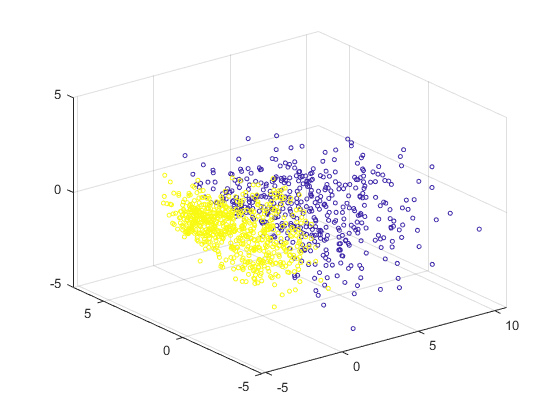


% Visualize groups
scatter3(scrs(:,1),scrs(:,2),scrs(:,3),10,g)

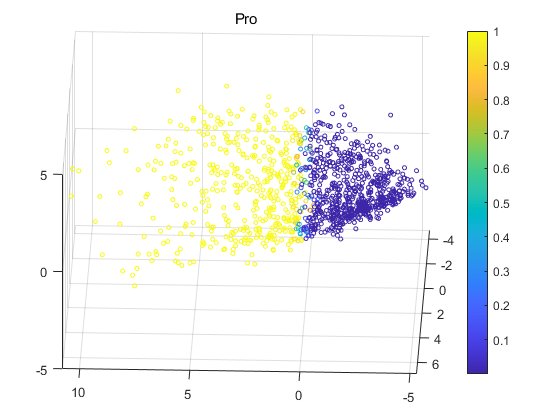


% Visualize probabilities
scatter3(scrs(:,1),scrs(:,2),scrs(:,3),10,p(:,1))
colorbar
view(110,40)
title("Pro")